Q2 b

%Define functions and variables:

alpha = 0.36;
delta = 0.025;
z=1;
rho = 0.95;
beta = 0.98;

l_s = 1/3;

syms c l k gamma;

u = gamma*log(c)+(1-gamma)*log(1-l);
f = (k^alpha)*(l^(1-alpha))+(1-delta)*k;

subs(diff(f,k),l,l_s)

$$ans = \frac{3\,3^{9/25}}{25\,k^{16/25}}+\frac{39}{40}$$


%Solve for k
eqn = subs(diff(f,k),l,l_s) == 1/beta

$$eqn = \frac{3\,3^{9/25}}{25\,k^{16/25}}+\frac{39}{40}=\frac{50}{49}$$

k_s = vpasolve(eqn, k)

$$k\_s = 8.4689511701574657061225168844509$$


%solve for c
c_s = vpa(subs(f,{k l},{k_s l_s})-k_s)

$$c\_s = 0.85649710246943984238790080055898$$


%solve for gamma
ul = diff(u, l);
uc = diff(u,c);
fl = diff(f,l);
eqn = subs(ul,{c l},{c_s l_s}) + subs(uc,{c l},{c_s l_s})*subs(fl, {k l},{k_s l_s})==0;
gamma_s = vpasolve(eqn, gamma)

$$gamma\_s = 0.38514680483592400690846286701209$$

Q2 c and d

Starting Dynare (version 5.5).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 4 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

k 		 8.46895
c 		 0.856497
l 		 0.333333
z 		 1

EIGENVALUES:
         Modulus             Real        Imaginary

          0.9405           0.9405                0
            0.95             0.95                0
           1.084            1.084                0
       2.132e+16        2.132e+16                0
             Inf             -Inf                0


There are 3 eigenvalue(s) larger than 1 in modulus 
for 3 forward-looking variable(s)

The rank condition is verified.


MODEL SUMMARY

  Number of variables:         4
  Number of stochastic shocks: 1
  Number of state variables:   2
  Number of jumpers:           3
  Number of static variable

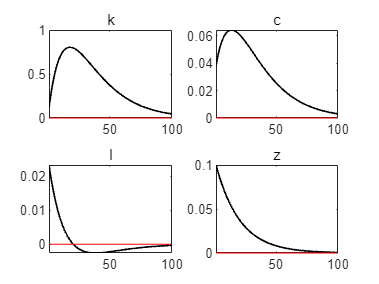

Total computing time : 0h00m08s


%with dynare
dynare model2.mod;